# Tarea 1. Estabilización de un sistema lineal de múltiples entradas

Marco Antonio Esquivel Basaldua

Se considera el siguiente sistema lineal de la forma


$$\dot{x} =\textrm{Ax}+\;\textrm{Bu}$$


donde

$A=\left\lbrack \begin{array}{cccc}
2 & -11 & 12 & 31\\
-3 & 13 & -11 & -33\\
4 & -25 & 14 & 51\\
-3 & 16 & -11 & -36
\end{array}\right\rbrack$,  $B=\left\lbrack \begin{array}{cc}
-1 & -4\\
1 & 6\\
-1 & -11\\
1 & 7
\end{array}\right\rbrack$

clear
A = [2 -11 12 31; -3 13 -11 -33; 4 -25 14 51; -3 16 -11 -36];
B = [-1 -4;1 6; -1 -11; 1 7];

Donde las dimensiones de la matriz $A$ son $n\times n=4\times 4$, y las dimensiones de $B$ son $n\times p=4\times 2$

[n, p] = size(B);

## 1) Simulación en lazo abierto

Simulación del comportamiento del sistema en lazo abierto con las condiciones iniciales


$$x_i =\left\lbrack \begin{array}{c}
1\\
-1\\
0\\
2
\end{array}\right\rbrack$$
 

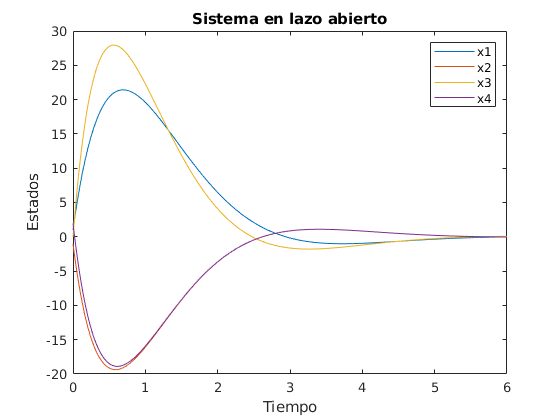

xi = [1 -1 0 2]';
x = xi;

dt = 0.01;
t = 0:dt:6;

for i = 1:length(t)-1
    xi = x(:,end);
    xi_1 = xi + dt*A*xi;
    
    x = [x xi_1];
end

figure
plot(t,x(1,:), t,x(2,:), t,x(3,:), t,x(4,:))
title('Sistema en lazo abierto')
xlabel('Tiempo')
ylabel('Estados')
legend('x1','x2','x3','x4')

Se puede observar que los estados del sistema convergen a cero, lo cual nos dice que es sistema es estable. Esto se puede verificar de igual forma calculando los valores propios de la matriz $A$ y comprobando que la parte real de ellos es negativa.

eig(A)

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -2.0000 + 0.0000i
  -3.0000 + 0.0000i


## 2) Controlabilidad

Se desea conocer si el sistema es controlable, para lo cual la matriz $\mathcal{C}$ debe tener rango $n=4$, que es el orden del sistema.


$$\mathcal{C} = [B, AB,A^2B,\cdots, A^{n-1}B]$$


n = 4;
C_ = [B A*B A^2*B A^3*B]

C_ =     -1    -4     6    11   -12   -27    16    73
     1     6    -6   -20    14    59   -24  -175
    -1   -11     8    37   -20  -111    36   331
     1     7    -6   -23    14    68   -24  -202


rank(C_)

ans = 4

Ya que $rank(\mathcal{C})=4$ se concluye que el sistema es controlable.

Otra forma de definir la controlabilidad del sistema es encontrando los índices de controlabilidad. Ya que el sistema es de dos entradas se contará con dos índices de controlabilidad, $\mu_1 ,\mu_2$.

mu = ctr_indeces(A,B)

mu =      2
     2


Seindo la suma $\mu_1 +\mu_2 =2+2=4+n$ se concluye que el sistema es cotrolable.

## 3) Transformación de similaridad

Se encuentra la transformación que lleva al sistema a la forma canónica controlable definiendo inicialmente la matriz $M$


$$M=\left\lbrack \begin{array}{ccccccccccccccc}
b_1  & {\textrm{Ab}}_1  & \cdots  & A^{\mu_1 -1} b_1  & \vdots  & b_2  & {\textrm{Ab}}_2  & \cdots  & A^{\mu_2 -1} b_2  & \vdots  & \cdots  & \vdots  & b_p  & \cdots  & A^{\mu_p -1} b_p 
\end{array}\right\rbrack$$


M = [];
for i = 1:p
    for j = 1:mu(i)
        M = [M A^(j-1)*B(:,i)];
    end
end
M

M =     -1     6    -4    11
     1    -6     6   -20
    -1     8   -11    37
     1    -6     7   -23


Se define la matriz de transformación como


$$T=\left\lbrack \begin{array}{c}
m_{1\mu_1 } \\
m_{1\mu_1 } A\\
m_{1\mu_1 } A^2 \\
\vdots \\
m_{1\mu_1 } A^{\mu_1 -1} \\
\vdots \\
m_{p\mu_p } \\
m_{p\mu_p } A\\
m_{p\mu_p } A^2 \\
\vdots \\
m_{p\mu_p } A^{\mu_p -1} 
\end{array}\right\rbrack$$


siendo


$$M^{-1} =\left\lbrack \begin{array}{c}
m_{11} \\
m_{12} \\
\vdots \\
m_{1\mu_1 } \\
\vdots \\
m_{\textrm{p1}} \\
m_{\textrm{p2}} \\
\vdots \\
m_{p\mu_p } 
\end{array}\right\rbrack$$


M_ = inv(M);
T = [];

index = 0;
for i = 1:p
    row = mu(i);
    for j = 1:row
        T = [T; M_(index+row,:)*A^(j-1)];
    end
    index = index + row;
end
T

T =     0.3333   -1.0000    0.5000    1.8333
    0.1667    0.1667    1.8333    2.8333
   -0.3333   -1.0000         0    0.6667
    0.3333    1.3333   -0.3333   -1.3333


Las transformaciones a las matrices $\bar{A}$ y $\bar{B}$ se realizan de la sigueinte forma.

$\bar{A} =\textrm{TA}T^1$,  $\bar{B} =\textrm{TB}$

A_ = T*A*inv(T)

A_ =     0.0000    1.0000    0.0000    0.0000
   -1.3333   -2.3333    2.6667    1.1667
   -0.0000   -0.0000   -0.0000    1.0000
   -2.0000   -0.6667   -5.0000   -4.6667


B_ = T*B

B_ =          0         0
    1.0000    0.0000
         0         0
    0.0000    1.0000


Por lo que el sistema en su forma canónica controlable resulta en la forma


$$\dot{\bar{x} } =\bar{A} \bar{x} +\bar{B} v$$



$$\dot{\bar{x} } =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{4}{3} & -\frac{7}{3} & \frac{8}{3} & \frac{7}{6}\\
0 & 0 & 0 & 1\\
-2 & -\frac{2}{3} & -5 & -\frac{14}{3}
\end{array}\right\rbrack \bar{x} +\left\lbrack \begin{array}{cc}
0 & 0\\
1 & 0\\
0 & 0\\
0 & 1
\end{array}\right\rbrack u$$


con $\bar{x} =T^{-1} x$

## 4) Diseño del controlador

Se desea simular e implementar un controlador de la forma $u=-\textrm{Kx}$ utilizando el método canónico asignando los polos en $\left\lbrace -5,-5,-3\pm 3j\right\rbrace$ a partir del estado inicial


$$x_1 =\left\lbrack \begin{array}{c}
1\\
-1\\
0\\
2
\end{array}\right\rbrack$$


Tomando como referencia el sistema transformado $\dot{\bar{x} } =\bar{A} \bar{x} +\bar{B} v$ se le aplica el control $v=-\bar{K} \bar{x}$, donde $K=\bar{K} T$. El sistema se escribe entonces como


$$\dot{\bar{x} } =\bar{A} \bar{x} +\bar{B} \left(-\bar{K} \bar{x} \right)=\bar{A} \bar{x} -\bar{B} \bar{K} \bar{x} =\left(\bar{A} -\bar{B} \bar{K} \right)\bar{x} =A_2 \bar{x}$$


Sea $\bar{K}$una matriz de dimensiones $p\times n=2\times 4$, sus entradas se definene de la forma


$$\bar{K} =\left\lbrack \begin{array}{cccc}
k_{11}  & k_{12}  & k_{13}  & k_{14} \\
k_{21}  & k_{22}  & k_{23}  & k_{24} 
\end{array}\right\rbrack$$


y la matriz $A_2 =\bar{A} -\bar{B} \bar{K}$se expresa como

syms k_11 k_12 k_13 k_14 k_21 k_22 k_23 k_24 s

K_ = [k_11 k_12 k_13 k_14;k_21 k_22 k_23 k_24]

$$K\_ = \left(\begin{array}{cccc} k_{11} & k_{12} & k_{13} & k_{14}\\ k_{21} & k_{22} & k_{23} & k_{24} \end{array}\right)$$

vpa(A_ - B_*K_)

$$ans = \left(\begin{array}{cccc} 0.0000000000000093258734068513149395585060119629 & 1.0 & 0.000000000000060396132539608515799045562744141 & 0.000000000000049737991503207013010978698730469\\ -1.0\,k_{11}-0.000000000000014210854715202003717422485351562\,k_{21}-1.3333333333333676762322284048423 & -1.0\,k_{12}-0.000000000000014210854715202003717422485351562\,k_{22}-2.3333333333333333333333333333333 & 2.6666666666666666666666666666667-0.000000000000014210854715202003717422485351562\,k_{23}-1.0\,k_{13} & 1.1666666666666666666666666666667-0.000000000000014210854715202003717422485351562\,k_{24}-1.0\,k_{14}\\ -0.0000000000000011102230246251565404236316680908 & -0.00000000000000022204460492503130808472633361816 & -0.0000000000000017763568394002504646778106689453 & 1.0\\ -0.0000000000000042188474935755948536098003387451\,k_{11}-1.0\,k_{21}-2.0 & -0.0000000000000042188474935755948536098003387451\,k_{12}-1.0\,k_{22}-0.66666666666666666666666666666667 & -0.0000000000000042188474935755948536098003387451\,k_{13}-1.0\,k_{23}-5.0 & -0.0000000000000042188474935755948536098003387451\,k_{14}-1.0\,k_{24}-4.6666666666666666666666666666667 \end{array}\right)$$

Al simplificar esta expresion se obtiene


$$\bar{A} -\bar{B} \bar{K} =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{4}{3}-k_{11}  & -\frac{7}{3}-k_{12}  & \frac{8}{3}-k_{13}  & \frac{7}{6}-k_{14} \\
0 & 0 & 0 & 1\\
-2-k_{21}  & -\frac{2}{3}-k_{22}  & -5-k_{23}  & -\frac{14}{3}-k_{24} 
\end{array}\right\rbrack$$


Los polos deseados son $s=\left\lbrace -5,-5,-3\pm 3j\right\rbrace$, por lo que el polinomio característico deseado se escribe como


$$\alpha \left(s\right)=\left(s+5\right)\left(s+5\right)\left(s^2 +6s+18\right)=s^4 +16s^3 +103s^2 +330s+450$$


Se define la matriz deseada en la forma canónica controlable como


$$A_c =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
-450 & -330 & -103 & -16
\end{array}\right\rbrack$$


Comparando las matrices $\left(\bar{A} -\bar{B} \bar{K} \right)$ y $A_c$ se observa que las siguientes relaciones se deben cumplir


$$-\frac{4}{3}-k_{11} =0$$



$$-\frac{7}{3}-k_{12} =0$$



$$\frac{8}{3}-k_{13} =1$$



$$\frac{7}{6}-k_{14} =0$$



$$-2-k_{21} =-450$$



$$-\frac{2}{3}-k_{22} =-330$$



$$-5-k_{23} =-103$$



$$-\frac{14}{3}-k_{24} =-16$$


por lo que la matriz $\bar{K}$resultante es


$$\bar{K} =\left\lbrack \begin{array}{cccc}
\frac{4}{3} & \frac{7}{3} & \frac{5}{3} & \frac{7}{6}\\
448 & \frac{988}{3} & 98 & \frac{34}{3}
\end{array}\right\rbrack$$


K_ = [4/3 7/3 5/3 7/6;448 988/3 98 34/3]

K_ =     1.3333    2.3333    1.6667    1.1667
  448.0000  329.3333   98.0000   11.3333


A partir de la cual se calculan los valores de la matriz $K=\bar{K} T$

K=K_*T

K = 	1.0e+03 *

    0.0007   -0.0011    0.0046    0.0086
    0.1753   -0.4760    0.8240    1.8047



$$K=\left\lbrack \begin{array}{cccc}
0\ldotp 7 & -1\ldotp 1 & 4\ldotp 6 & 8\ldotp 6\\
175\ldotp 3 & -476 & 824 & 1804\ldotp 7
\end{array}\right\rbrack$$


Al igual que en el punto 1, se realiza la simulación del sistema con el estado inicial $x_i =\left\lbrack \begin{array}{c}
1\\
-1\\
0\\
2
\end{array}\right\rbrack$pero en este caso realimentado con el vector de entradas $u=-\textrm{Kx}$.

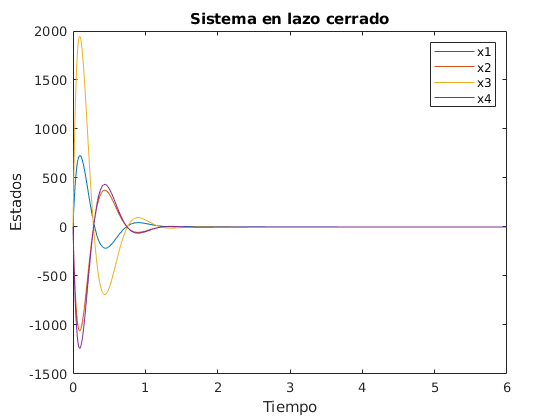

xi = [1 -1 0 2]';
x = xi;

dt = 0.01;
t = 0:dt:6;

for i = 1:length(t)-1
    xi = x(:,end);
    u = -K*xi;
    xi_1 = xi + dt*(A*xi +B*u);
    
    x = [x xi_1];
end

figure
plot(t,x(1,:), t,x(2,:), t,x(3,:), t,x(4,:))
title('Sistema en lazo cerrado')
xlabel('Tiempo')
ylabel('Estados')
legend('x1','x2','x3','x4')

A partir de las gráficas obtenidas se observa que el sistema cerrado sigue siendo estable, sin embargo el tiempo para que los estados lleguen a cero se redujo de cerca de cinco segundos a poco más de un segundo aunque se tienen sobreimpulsos muy pronunciados.